# 8.Count the number of coins in an image.

## Step-1:Import the image

Imports the image needed to be detected using imshow command.

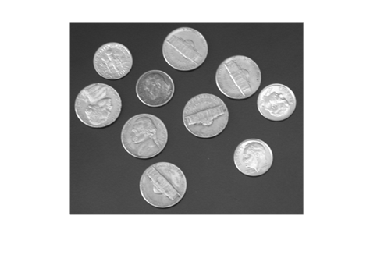

% Read the input image
img = imread('coins.png');
imshow(img);

## Step-2:Convert to Grayscale

converrts the normal image to the graysacle for easy detection of the coins.

th_val_auto=graythresh(img)

th_val_auto = 0.4941

th_int_auto=th_val_auto*255

th_int_auto = 126

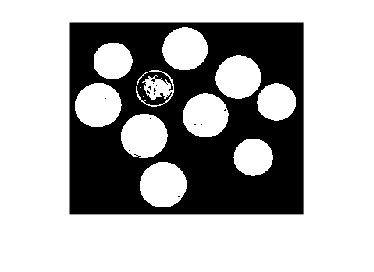

bin_img=imbinarize(img,th_val_auto);
imshow(bin_img)

## Step-3:Remove noise

Here we can observe that imfill fills the gap found in the coins(bianry object) which helps in finding the uneven lighting and gaps present due to some reflections.Bwreaopen is the command used to remove the noise such as unwanted objects in the image.

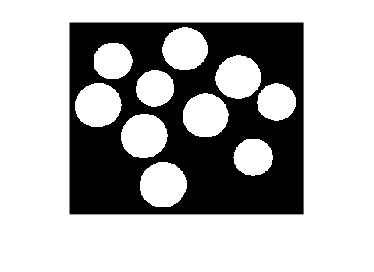

bin_img = imfill(bin_img, 'holes'); % Fill holes in the coins
bin_img = bwareaopen(bin_img, 100); % Remove small noise
figure;
imshow(bin_img)

## Step-4:Count the number of coins

counts the number of coins using the binarized image.

[labels, numCoins] = bwlabel(bin_img);
disp(['Number of Coins Detected: ', num2str(numCoins)]);

Number of Coins Detected: 10


## Step-5:Display the result

It detects the coins by plotting the red stars at their centroids and displays the original image of the coins being detected.

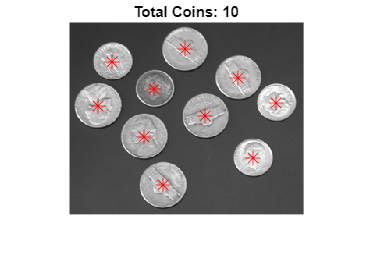

stats = regionprops(labels, 'Centroid');
figure;
imshow(img);
title(['Total Coins: ', num2str(numCoins)]);
hold on;

for i = 1:numCoins
    centroid = stats(i).Centroid;
    plot(centroid(1), centroid(2), 'r*', 'MarkerSize', 10);
end